# Iterative fitting for multiple waves

In this example, the generalized SEIR model is automatically fitted to multiple provinces in China. As in the previous examples, I am taking some data, collected into DATA.mat from John Hopkins university [1]. To keep the computation as short as possible, the option "iter" is removed using an optional argument.

**Only Provinces with multiple epidemic waves are selected**

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Load the data

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 20-Jun-2020



Location = 'China';

try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ;
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ;
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));
end

disp(tableConfirmed(indC,1:2))

     ProvinceState      CountryRegion
    ________________    _____________

    "Anhui"                "China"   
    "Beijing"              "China"   
    "Chongqing"            "China"   
    "Fujian"               "China"   
    "Gansu"                "China"   
    "Guangdong"            "China"   
    "Guangxi"              "China"   
    "Guizhou"              "China"   
    "Hainan"               "China"   
    "Hebei"                "China"   
    "Heilongjiang"         "China"   
    "Henan"                "China"   
    "Hong Kong"            "China"   
    "Hubei"                "China"   
    "Hunan"                "China"   
    "Inner Mongolia"       "China"   
    "Jiangsu"              "China"   
    "Jiangxi"              "China"   
    "Jilin"                "China"   
    "Liaoning"             "China"   
    "Macau"                "China"   
    "Ningxia"              "China"   
    "Qinghai"      

##  Initial guess and initial conditions

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 0.9; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.5,20]; % recovery rate
kappa_guess = [0.001,0.001,10]; % death rate
guess = [alpha_guess,beta_guess,1/LT_guess,Q_guess,lambda_guess,kappa_guess];

Npop= 14e6; % population
tStart1 = datetime(2020,02,01); % Beginning of the first wave
tEnd = datetime(2020,07,01); % End of simulation
timeRef = time;

## Main loop

The intiial number of exposed and infectious has a non-negligible influence on the outcome of the fit. A poor fit can be linked to the wrong choice of E0 and I0

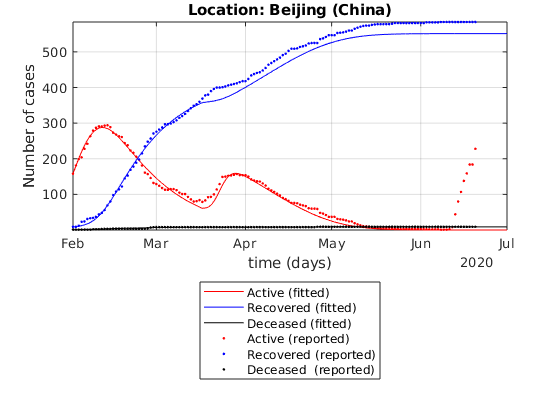

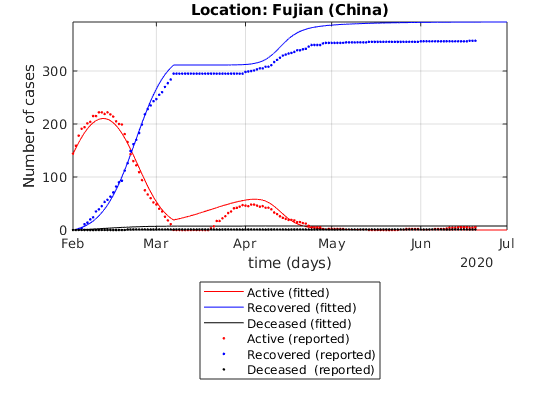

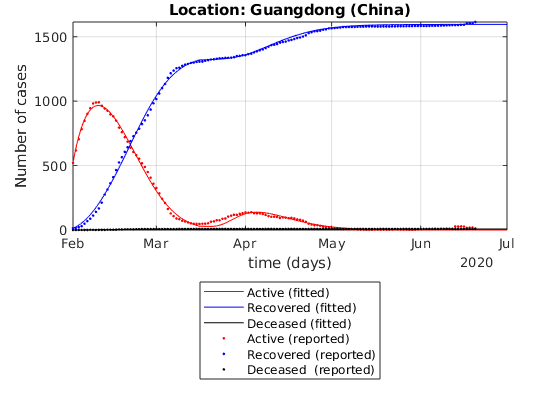

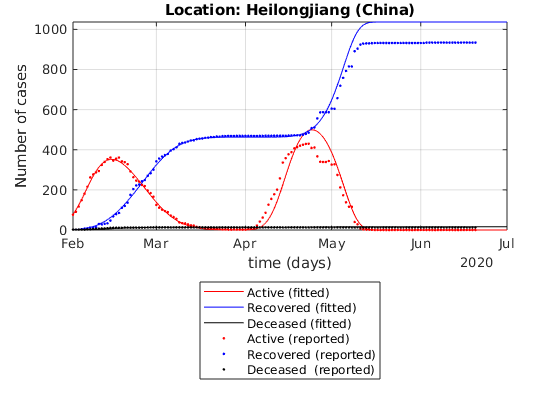

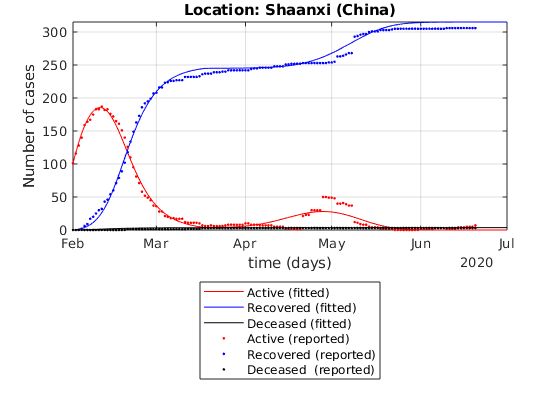

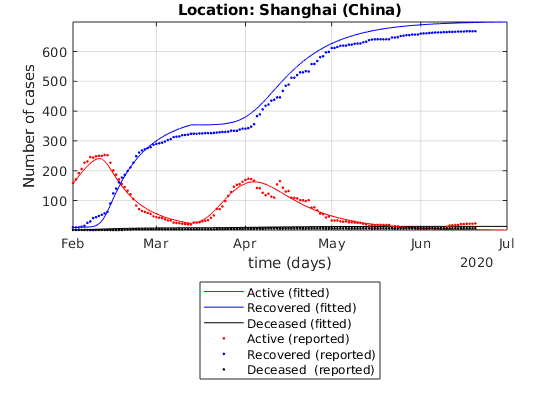

for ii = 1:min([numel(indR),numel(indC),numel(indD)])
    time = timeRef;
    Recovered = table2array(tableRecovered(indR(ii),5:end));
    Deaths = table2array(tableDeaths(indD(ii),5:end));
    Confirmed = table2array(tableConfirmed(indC(ii),5:end));
    
    Confirmed(time<tStart1) = [];
    Recovered(time<tStart1) = [];
    Deaths(time<tStart1) = [];
    time(time<tStart1) = [];
    
    Active = Confirmed-Recovered-Deaths;
    Active(Active<0) = 0; % No negative number possible
    
    
    % get lowest values before the second wave: This give the new initial
    % time
    [~,indMin] = min(Active(1:60));
    
    tStart2 = time(indMin);
    
    % Run simulation if enough data for the second wave
    if any(ii == [2,4,6,11,24,26])
        
        % Function that fit and simulate the different cases if two
        % epidemic waves are detected
        [Q,R,D,newT] = getMultipleWaves(guess,Npop,time,Confirmed,Recovered,Deaths,...
            tStart1,tStart2,tEnd);
        
        figure
        semilogy(newT,Q,'r',newT,R,'b',newT,D,'k');
        hold on
        semilogy(time,Active,'r.',time,Recovered,'b.',time,Deaths,'k.');
        % ylim([0,1.1*Npop])
        ylabel('Number of cases')
        xlabel('time (days)')
        leg = {'Active (fitted)',...
            'Recovered (fitted)','Deceased (fitted)',...
            'Active (reported)','Recovered (reported)','Deceased  (reported)'};
        legend(leg{:},'location','southoutside')
        set(gcf,'color','w')
        grid on
        axis tight
        set(gca,'yscale','lin')
        subLoc = char(table2array(tableRecovered(indR(ii),1)));
        Loc = char(table2array(tableRecovered(indR(ii),2)));
        title(['Location: ',subLoc,' (',Loc,')'])
        pause(1)
    end
end